Month long data set

clear
load data2.mat
n=length(data.CzasLokalnyUTC0000);

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);
day=24*60*60*fs

day = 17280

data=data(1:n,:);
% t_all=T*(0:day-1);


Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
all_data=length(X)

all_data = 516457

t=T*(1:all_data);
X=X';
X=X(:,1:all_data);
size(X)

ans =            8      516457


## Interpolation

X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

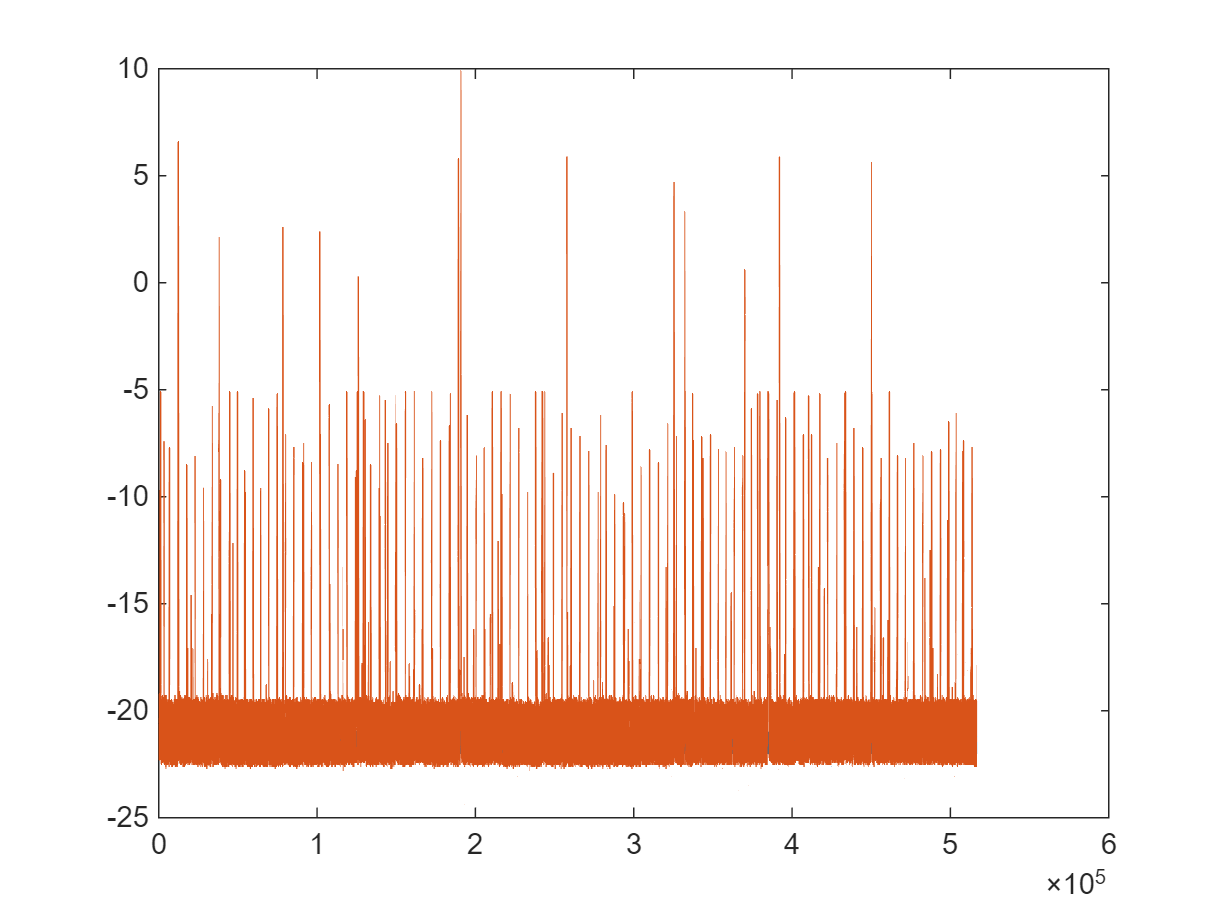

figure
plot(-22.+X(2,:));hold on;
plot(X_filtered(3,:));

We see that there is a temporal shift betwee the temperature peak and compressor turning on

There is a temporal shift between the valley of the temp and the compresor turning off.

Ideally the shift on the peak would equal the shift of the valley. In this dataset it is pretty close, hence the peak detection algo had better results than the graybox.

The idea here could be:

Assuming we know:

physical parameters like compressor efficiency, tharmal isolation and themral mass (load)

We can:

Run a simulation and get the supposed

## Remooving anomalies


anomaly_locs=compressorCycles(Kompresor1);%for operating on anomaly

compressor_locs=anomaly_locs;%for operating on all locs


features = FeatureExtract(X_filtered(3,:),anomaly_locs);
f1=zeros(1,length(anomaly_locs)-1);
for i=1:length(anomaly_locs)-1
    f1(i)=anomaly_locs(i+1)-anomaly_locs(i);
end
anomaly_locs=anomaly_locs(2:end);
fridge_air_temp_p2p=features(1,:)-features(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
for i=2:length(features)
    
    if (TF(i)==0)
        indexContainer{set}=[indexContainer{set},anomaly_locs(i-1):anomaly_locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end

### Setting proper index container length 

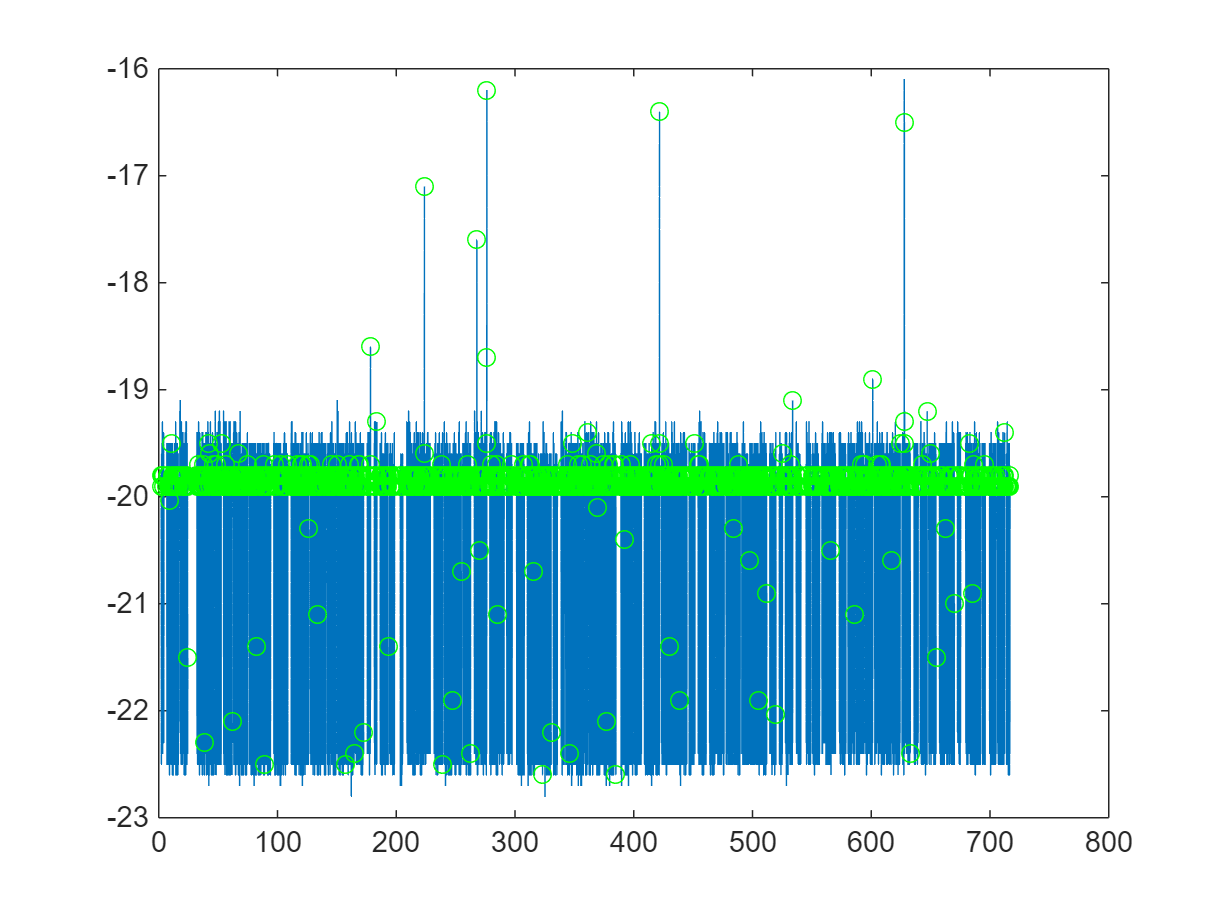

set=1;
usableDataIndex_length = 0;

clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*60*2*fs
        usableDataIndex{set}=indexContainer{i};
        usableDataIndex_length = usableDataIndex_length + length(indexContainer{i});
        set=set+1;
    end
end

%extracts compressor locs but only the ones present in usableDataIndex
compressor_locs=compressor_locs(ismember(compressor_locs, [usableDataIndex{:}]));

figure
for i = 1:length(usableDataIndex)
    plot(t_all(usableDataIndex{i})/60/60,X_filtered(3,usableDataIndex{i}),"Color","#0072BD");hold on
    plot(t_all(compressor_locs)/60/60, ...
        X_filtered(3,compressor_locs),'o',"Color","#00FF00")
end

load MergeAlgoAll.mat
% y=cell(1,length(usableDataIndex));
% params=cell(1,length(usableDataIndex));
% parfor i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y{i},params{i}]=GATrain(X(2,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
%         t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
% end
% 
% save MergeAlgoAll y params

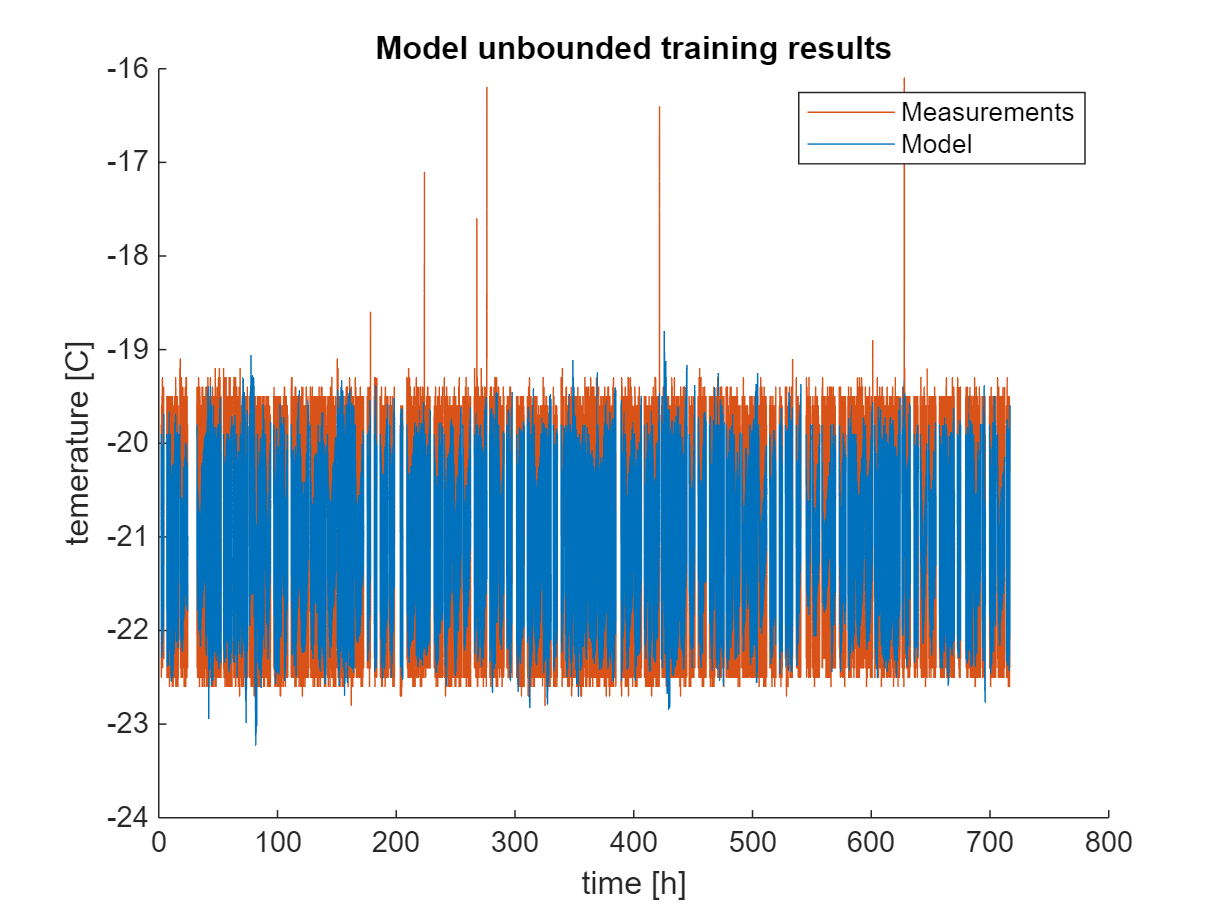

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t_all(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t_all(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

TrainingFraction=0.3;  % percent of dataset used for training
TrainingNumber=floor(TrainingFraction*length(usableDataIndex));
TrainingData=usableDataIndex(1:TrainingNumber);
TestingData=usableDataIndex(TrainingNumber+1:end);

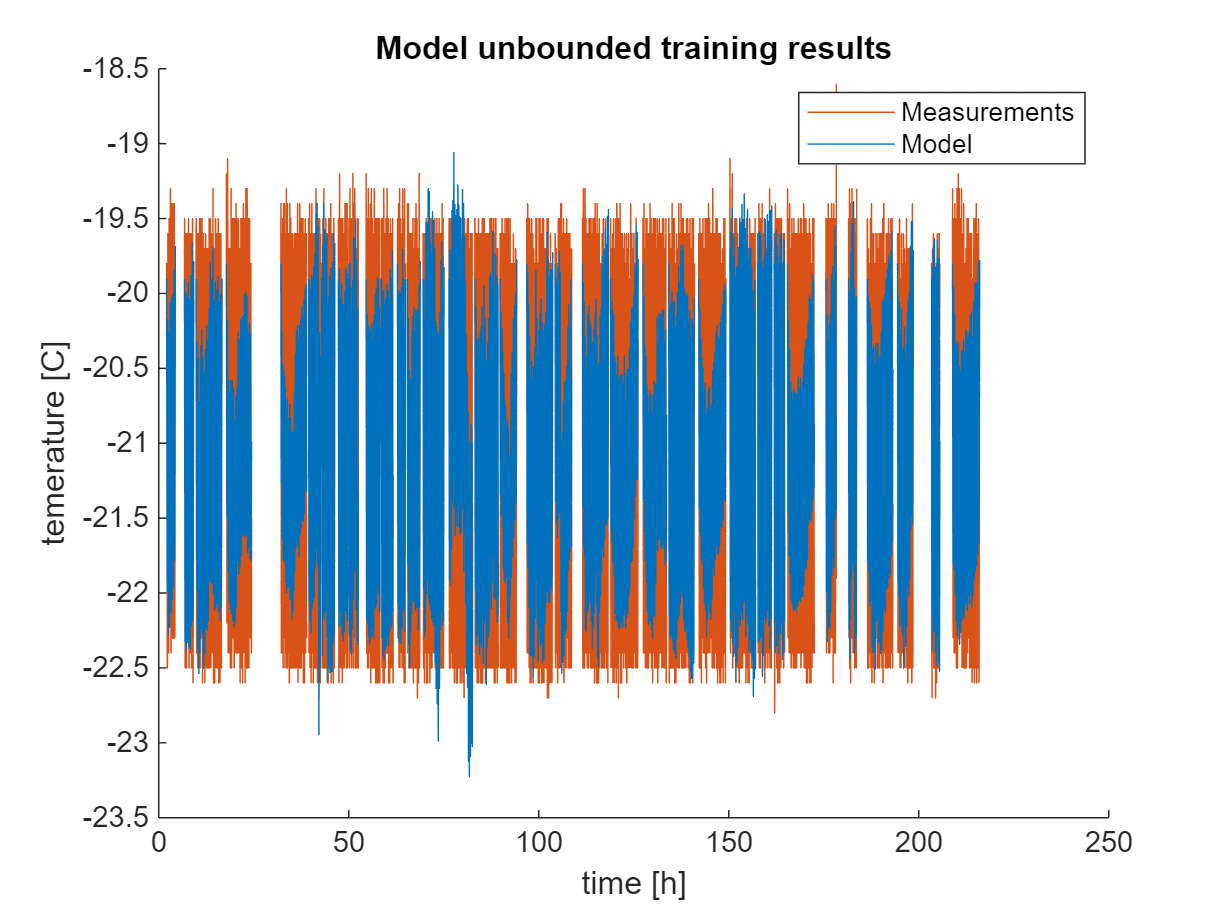

figure
hold on
for i = 1:length(TrainingData)
% for i = 1:3
    plot(t(TrainingData{i})/(60*60),X_filtered(3,TrainingData{i}),'Color','#D95319')
    plot(t(TrainingData{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

for i = 1:length(params)
resu(i,:)=params{i};
end


% figure
% plot3(resu(:,1),resu(:,2),resu(:,3),'o');
% grid on
% xlabel('G')
% ylabel('R')
% zlabel('C')
% title('Plot of parameter value results')
% % view(0,0)
% view(0,90)

Results analysys

for i = 1:length(TrainingData)
rmse_mat(i)=rmse(X_filtered(3,TrainingData{i})',y{i});
end

[rmse_mat_sorted, sort_indeces] = sort(rmse_mat);

% function bestParameter=bestOfDataSet(TrainingSet,params,T)
TrainingSet=TrainingData;


averageRMSE=NaN(1,length(TrainingSet));
parfor j=1:length(TrainingSet) %for parameter set j
    RMSE_on_all=NaN(1,length(TrainingSet));
    for i=1:length(TrainingSet) %check rmse of j parameter set on all data chinks
        t_sim=T*(0:length(usableDataIndex{i})-1);
        RMSE_on_all(i) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{j}(1), params{j}(2), params{j}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
    end

    if any(isnan(RMSE_on_all), 'all')
        error('Array RMSE_on_all contains NaN values.');
    end

    averageRMSE(j)=mean(RMSE_on_all); %average rmse for j parameter set on all data chunks

end

if any(isnan(averageRMSE), 'all')
    error('Array averageRMSE contains NaN values.');
end

[~,ind] = min(averageRMSE);
bestParameter=params(ind);

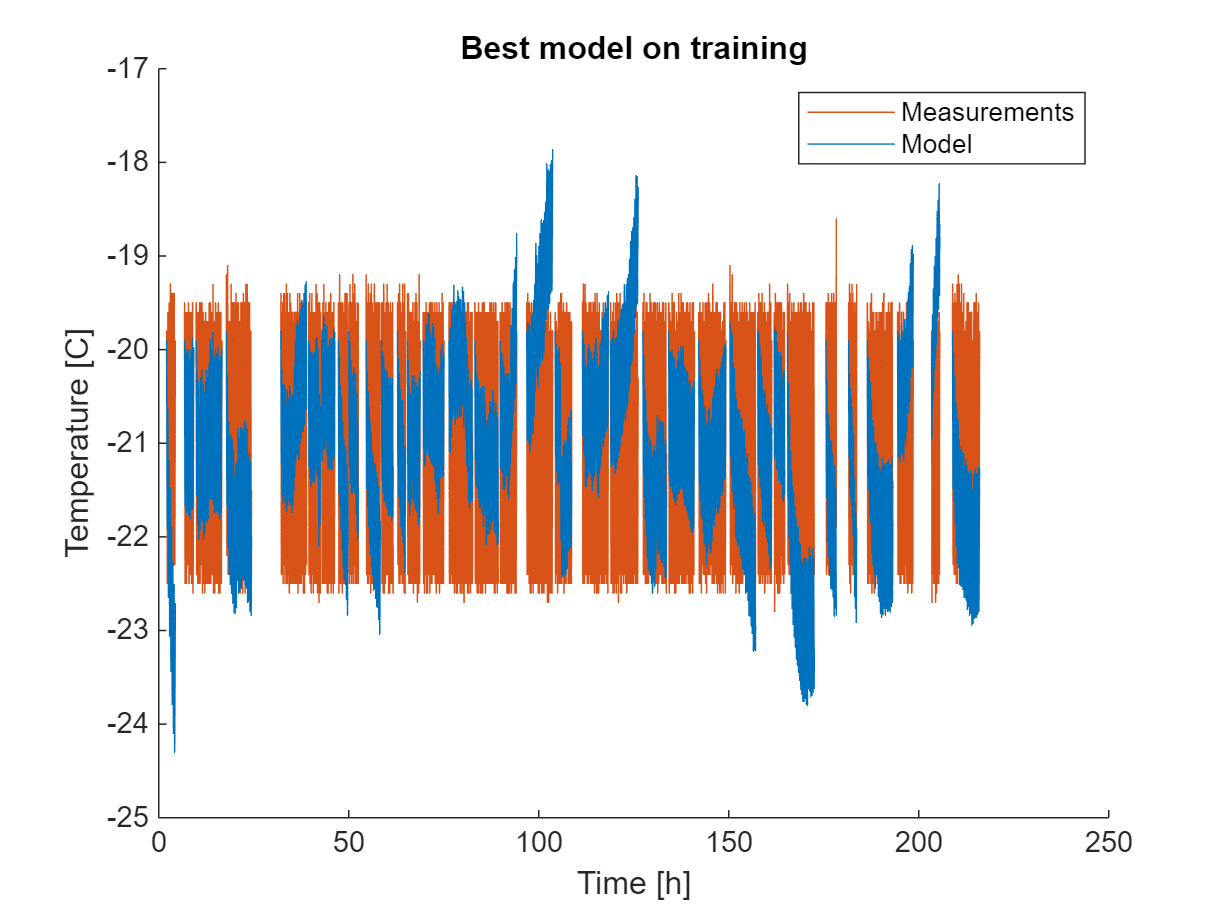


figure
hold on
for i = 1:TrainingNumber
% for i = 1:3
    t_sim=T*(0:length(TrainingData{i})-1);
    y_tmp=ModelFunction(-X(2,TrainingData{i})', X_filtered(1,TrainingData{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X_filtered(3,TrainingData{i}(1)))';

    plot(t(TrainingData{i})/(60*60),X_filtered(3,TrainingData{i}),'Color','#D95319')
    plot(t(TrainingData{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

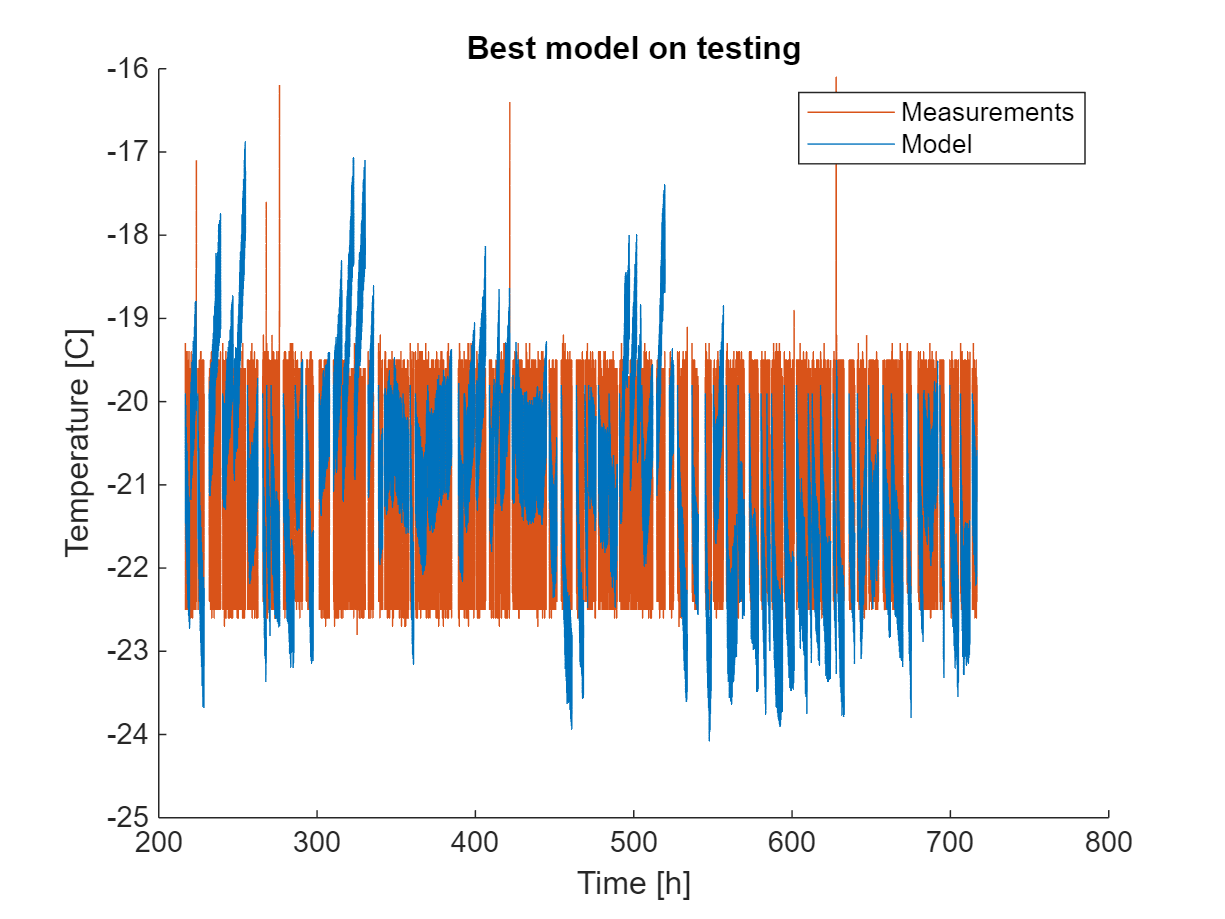

figure
hold on
for i = TrainingNumber+1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

min(averageRMSE)

ans = 1.0099

clear RMSE_on_all_testing
count=1;
for i=TrainingNumber+1:length(usableDataIndex)
    t_sim=T*(0:length(usableDataIndex{i})-1);
    RMSE_on_all_testing(count) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
        params{ind}(1), params{ind}(2), params{ind}(3),...
        t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
   count=count+1;
end
mean(RMSE_on_all_testing)

ans = 1.1949

(mean(RMSE_on_all_testing)-min(averageRMSE))/min(averageRMSE)

ans = 0.1832

So the rmse on testing is 18% worst than on training 

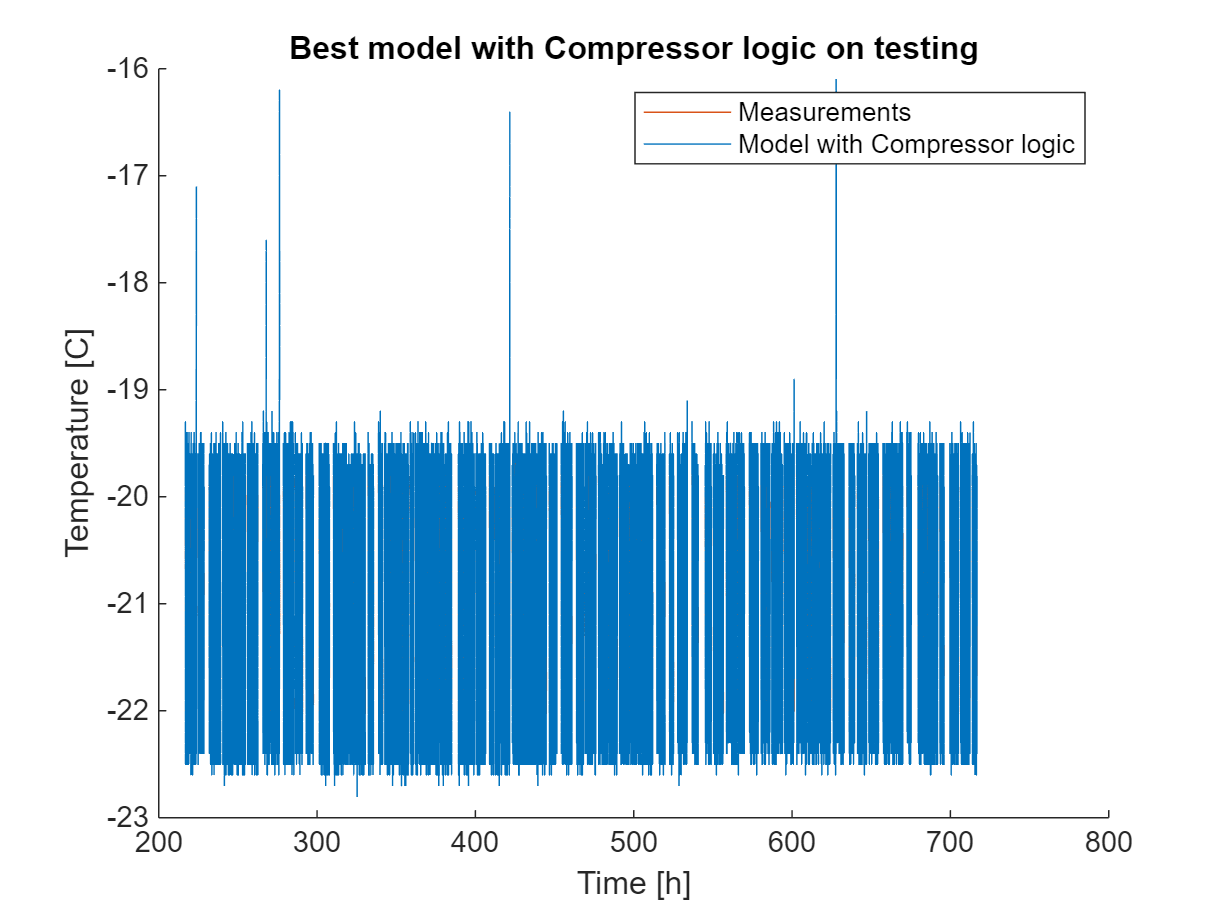

figure
hold on
count=1;
for i = TrainingNumber+1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)))';

    simData = fridge_fixed_stepCopy(X_filtered(1,usableDataIndex{i})',params{ind}(1), params{ind}(2), params{ind}(3),t_sim,X_filtered(3,usableDataIndex{i}(1))');
    plot(t(usableDataIndex{i})/(60*60),simData.y,'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#0072BD')
    compare_container.mask_pred{count}=simData.u1;
    compare_container.mask_meas{count}=-X(2,usableDataIndex{i});
    count=count+1;
    % plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
    clear simData
end
hold off
title('Best model with Compressor logic on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model with Compressor logic')

for i=1:length(compare_container.mask_pred)
stats(i) = compareOnTime(compare_container.mask_pred{i}, compare_container.mask_meas{i});
v(i)=stats(i).pctError;
end
mean(abs(v))

ans = 5.2469

results = analyzeCompressorMaskFromGrayBox(compare_container,'plot',false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -52.0 s (-5.9%)

--- Segment 2 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = +63.0 s (6.2%)

--- Segment 3 ---
Measured ON-time   = 0.4 h
Predicted ON-time  = 0.3 h
Difference         = -86.0 s (-6.6%)

--- Segment 4 ---
Measured ON-time   = 0.6 h
Predicted ON-time  = 0.6 h
Difference         = +144.0 s (7.3%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +68.0 s (3.8%)

--- Segment 6 ---
Measured ON-time   = 0.6 h
Predicted ON-time  = 0.6 h
Difference         = +196.0 s (9.9%)

--- Segment 7 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -17.0 s (-0.9%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -53.0 s (-6.9%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -3.0 s (-0.4%)

--- Segment 1

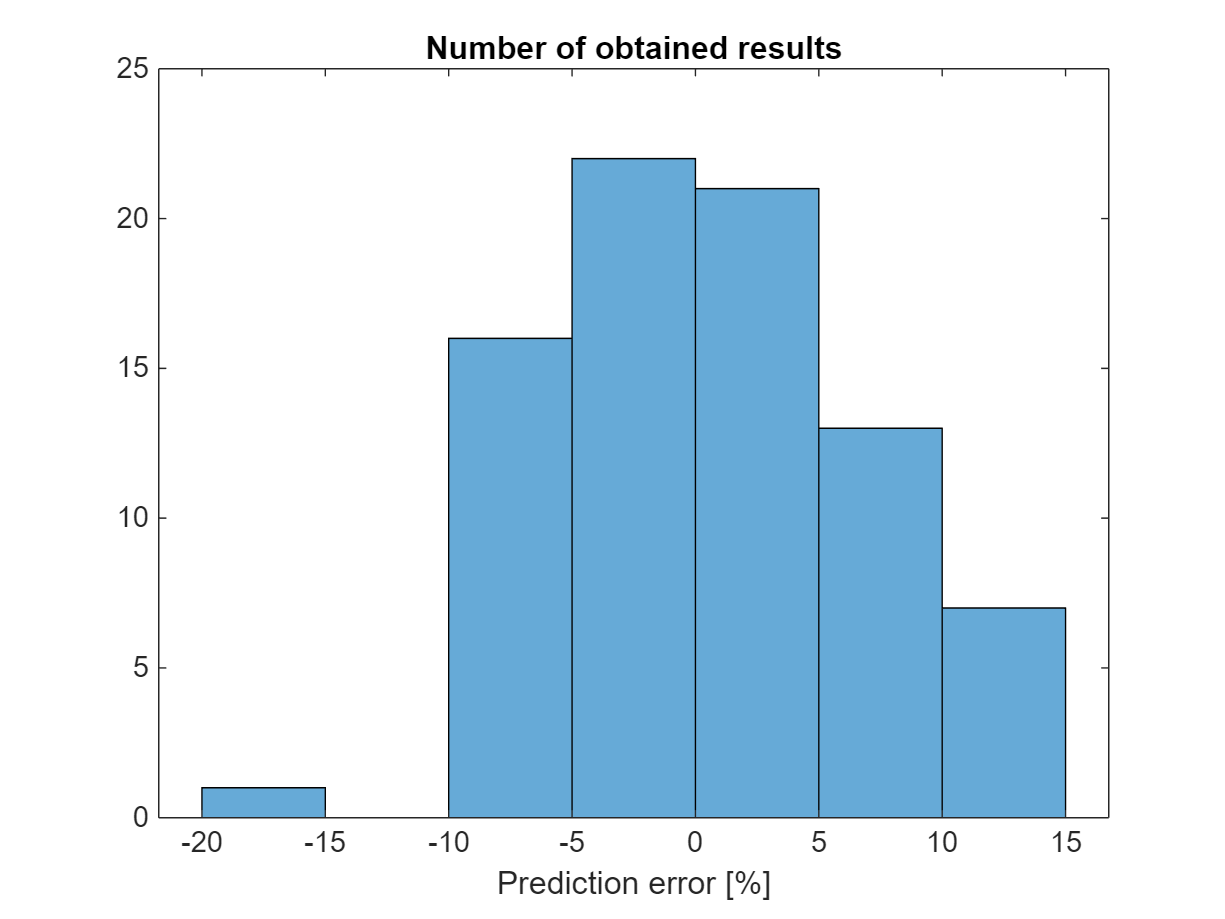

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

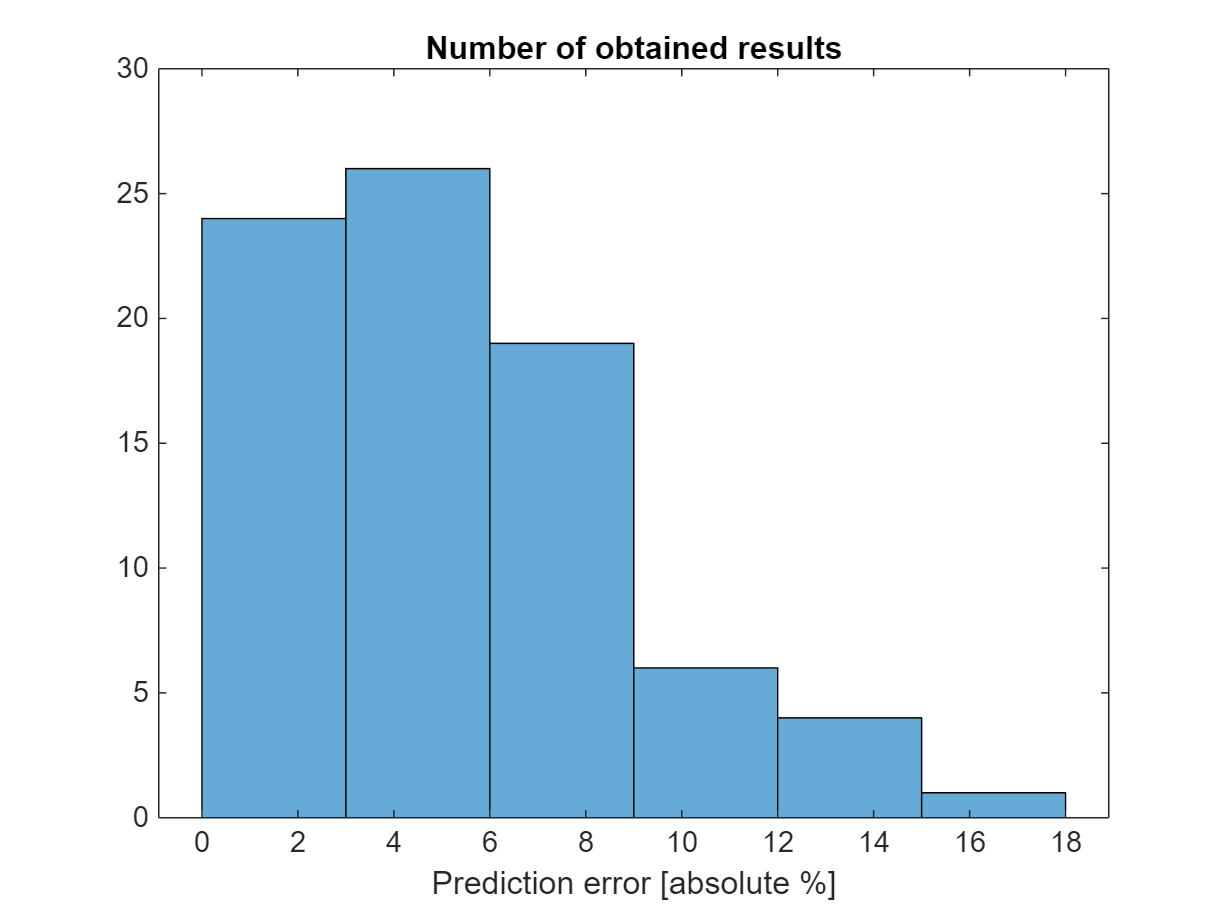

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

idx_badResults = find(abs(pctErrorVector) > 10)

idx_badResults =     17    18    45    47    49    50    66


7 results with error > 10%

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   5.2469


## Now let's see how indentifying the offset between the compressor state change and temperature peak impacks our simple algo

Let's take one chunk:

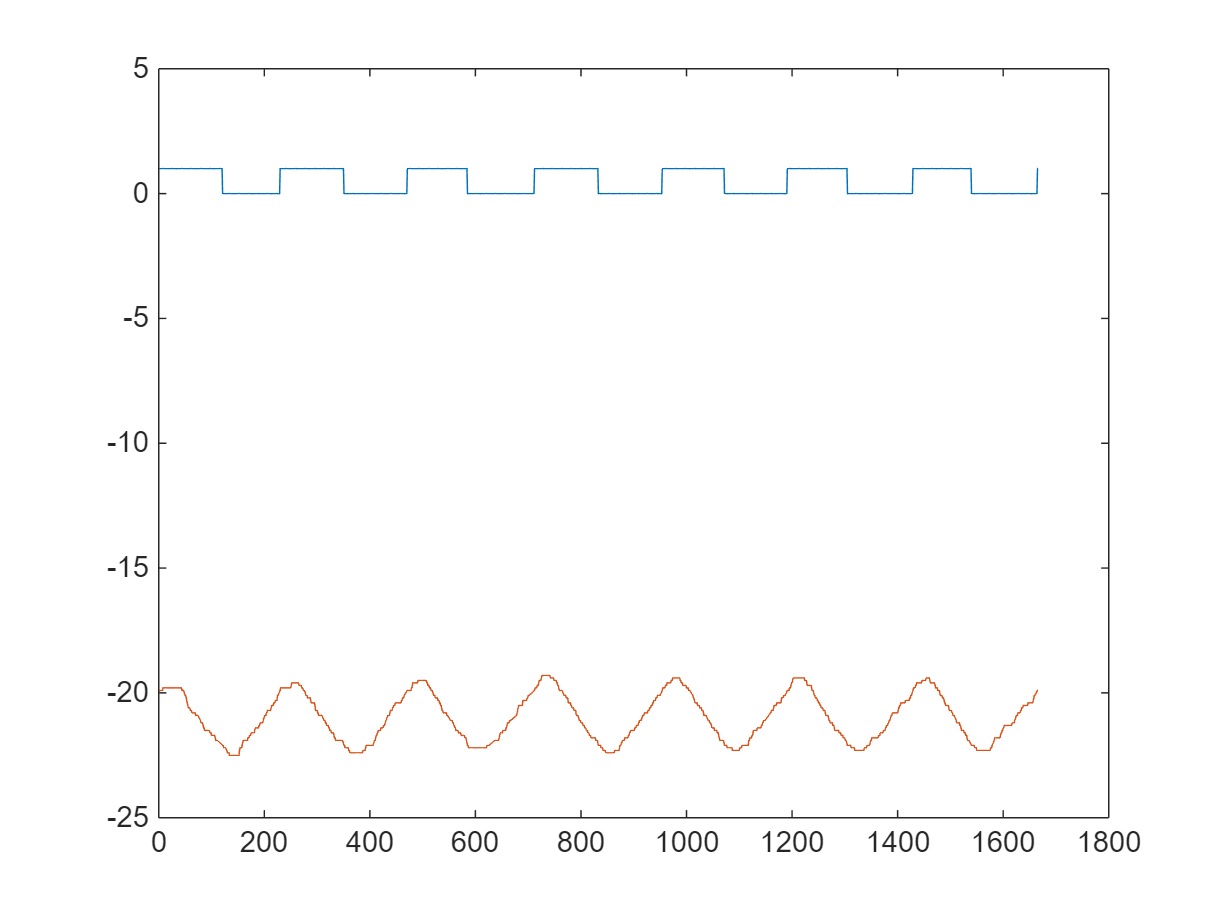

plot(X(2,TrainingData{1}));hold on
plot(X_filtered(3,TrainingData{1}));hold off

We identify the peaks and valleys and select a offset that will minimise the error

results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), usableDataIndex(1), ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -25.0 s (-3.7%)



Above without offset

Below we find the optimal offset

calib = estimatePeakValleyOffsetsFromLabels(t, X_filtered(3,:), X(2,:), usableDataIndex(1))

Estimated offsets from labeled data:
  PeakOffset   = -20 samples
  ValleyOffset = -13 samples
  Peak matches   : 6
  Valley matches : 7


calib = struct with fields:
        PeakOffset: -20
      ValleyOffset: -13
         PeakDiffs: [-22 -20 -14 -20 -11 -25]
       ValleyDiffs: [-13 -11 -2 -14 -15 -14 -10]
      nPeakMatches: 6
    nValleyMatches: 7
        perSegment: [1×1 struct]
          settings: [1×1 struct]


We use the optimal offset below

results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), usableDataIndex(1), ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -3.0 s (-0.4%)



We get best coverage

Sanity check: On training without offset calibration:

results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), TrainingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -25.0 s (-3.7%)

--- Segment 2 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -14.0 s (-2.4%)

--- Segment 3 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +23.0 s (1.3%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -8.0 s (-0.4%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +28.0 s (1.5%)

--- Segment 6 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +7.0 s (0.8%)

--- Segment 7 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.2 h
Difference         = -6.0 s (-0.7%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -14.0 s (-1.9%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +0.0 s (0.0%)

--- Segment 10 ---

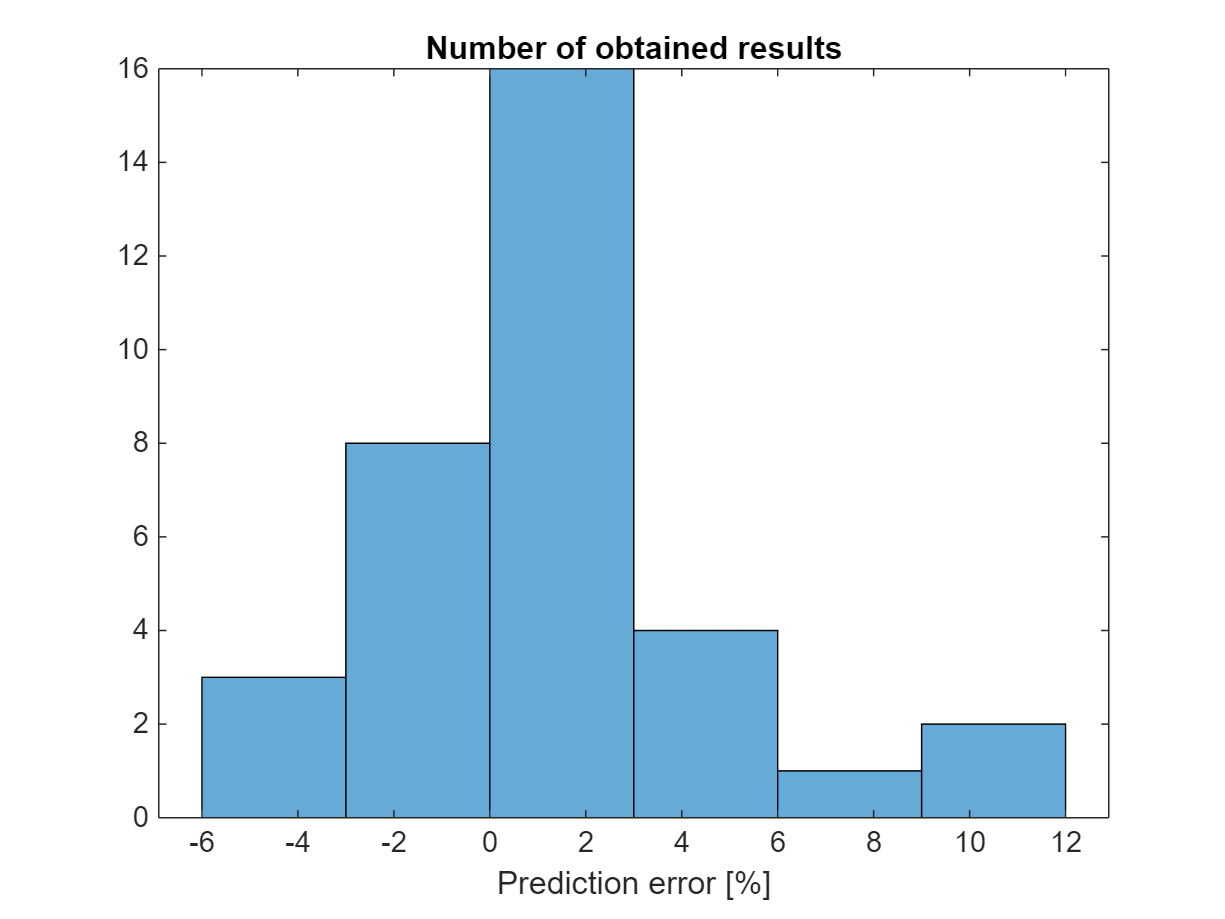

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

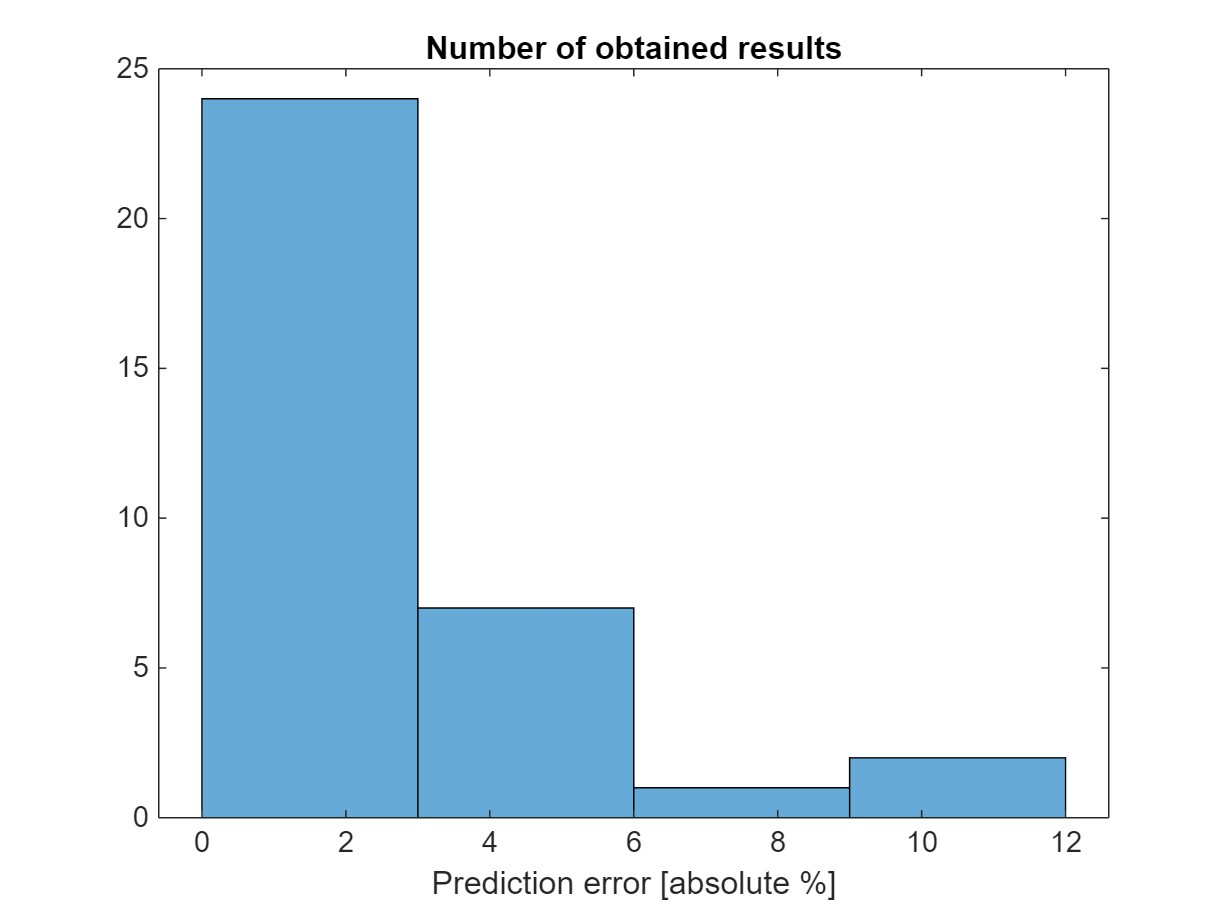

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

idx_badResults = find(abs(pctErrorVector) > 10);
length(idx_badResults)

ans = 0

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   2.4122


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        5.483667e+02


On  training with calibration

clear calib
clear results
calib = estimatePeakValleyOffsetsFromLabels(t, X_filtered(3,:), X(2,:), TrainingData)

Estimated offsets from labeled data:
  PeakOffset   = -13 samples
  ValleyOffset = -12 samples
  Peak matches   : 558
  Valley matches : 583


calib = struct with fields:
        PeakOffset: -13
      ValleyOffset: -12
         PeakDiffs: [-22 -20 -14 -20 -11 -25 -10 -8 -17 -17 -17 -22 -12 -23 -1 -24 -12 -14 -18 -12 -17 -5 -17 -16 -9 -25 -13 -14 -4 -22 -5 -15 -19 -18 -13 -17 -7 -21 -12 -19 -14 -18 -16 -14 -13 -22 -20 -18 -14 -15 -21 -13 -13 -5 -14 … ] (1×558 double)
       ValleyDiffs: [-13 -11 -2 -14 -15 -14 -10 -10 -10 -11 -11 -12 -10 -14 -12 -9 -12 -15 -12 -12 -10 -19 -11 -11 -17 -10 -17 -10 -21 -22 -11 -14 -21 -20 -16 -5 -7 -22 -14 -9 -10 -14 -12 -13 -16 -12 -21 -19 -15 -20 -14 -13 -13 -17 -11 … ] (1×583 double)
      nPeakMatches: 558
    nValleyMatches: 583
        perSegment: [1×34 struct]
          settings: [1×1 struct]


results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), TrainingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -32.0 s (-4.6%)

--- Segment 2 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -18.0 s (-3.0%)

--- Segment 3 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +31.0 s (1.7%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -1.0 s (-0.1%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +53.0 s (2.8%)

--- Segment 6 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +5.0 s (0.6%)

--- Segment 7 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = -7.0 s (-0.8%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -19.0 s (-2.5%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -4.0 s (-0.6%)

--- Segment 10 --

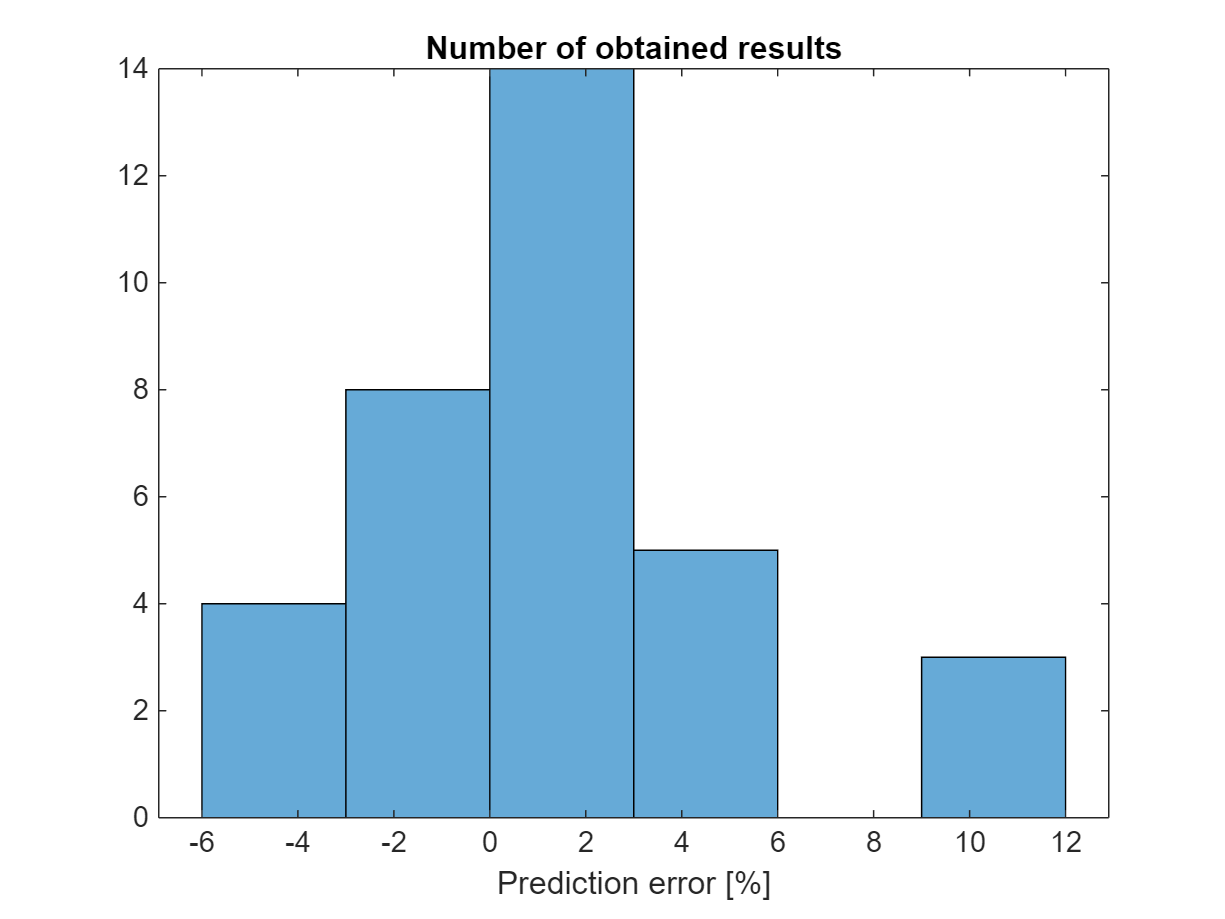

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

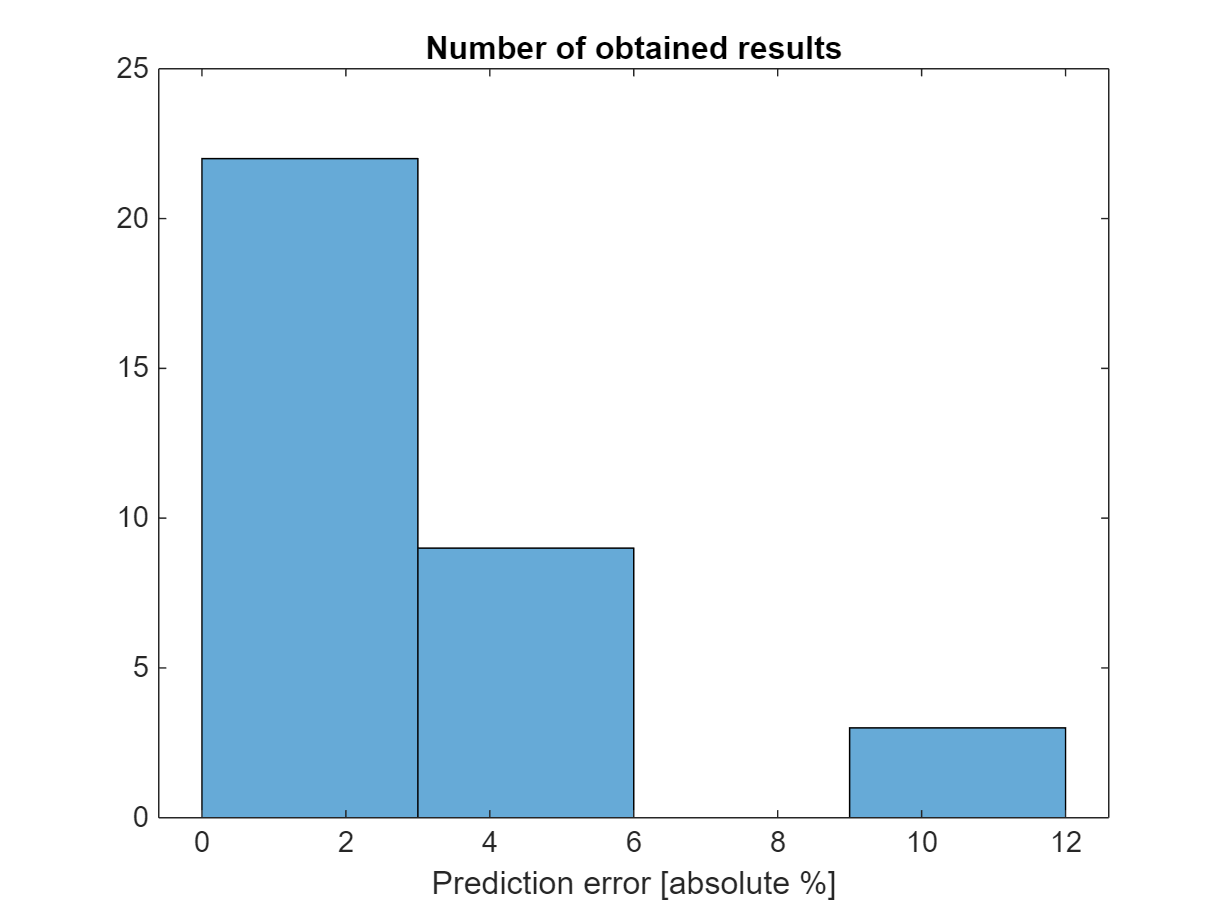

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)

ans = 1

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   2.8124


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        5.483667e+02


The MAPE is bigger on the calibrated set than on the set without offset

## Now trying the MAPE on testing with vs without calibration:

results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), TestingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -11.0 s (-1.4%)

--- Segment 2 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = -13.0 s (-1.4%)

--- Segment 3 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = +10.0 s (0.8%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +40.0 s (2.1%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +87.0 s (5.1%)

--- Segment 6 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.6 h
Difference         = +91.0 s (4.8%)

--- Segment 7 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +24.0 s (1.3%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -19.0 s (-3.0%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +7.0 s (1.1%)

--- Segment 10 --

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)

ans = 0

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   2.2735


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        5.483667e+02



results = analyzeCompressorSegments( ...
    t, X_filtered(3,:), X(2,:), TestingData, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PeakOffset', calib.PeakOffset, ...
    'ValleyOffset', calib.ValleyOffset,...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -15.0 s (-1.9%)

--- Segment 2 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = -13.0 s (-1.4%)

--- Segment 3 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = +10.0 s (0.8%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.6 h
Difference         = +70.0 s (3.7%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +112.0 s (6.5%)

--- Segment 6 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.6 h
Difference         = +109.0 s (5.7%)

--- Segment 7 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +46.0 s (2.5%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -25.0 s (-3.9%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +1.0 s (0.2%)

--- Segment 10 

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
idx_badResults = find(abs(pctErrorVector) > 10); 
length(idx_badResults)

ans = 0

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   2.4787


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        5.483667e+02


function simData = fridge_fixed_stepCopy(Ta,G,R,c,t,x0)
% Discrete-time simulation of a refrigerator with hysteresis control
% ––– USER DEFINED SYSTEM ––– ------------------------------------------

% G=2.1686;   
% R=48.9120; 
% c=114.2959;

A=-1/(R*c);
B=[G/c,1/(R*c)];
C=1;
D=[0,0];

dt     = t(2)-t(1);                % time step [s]
Tend   = t(end);           % simulate 2 hours
% t      = 0:dt:Tend;        % time vector
Ta_fun = @(t) Ta((t/dt)+1);  % outdoor temperature

n   = size(A,1);
x   = zeros(n,length(t));
% x0  = zeros(n,1);         % initial state
x(:,1) = x0;

y  = zeros(1,length(t));
u1 = zeros(1,length(t));
u2 = arrayfun(Ta_fun, t);

% ––– Hysteresis controller state
heater = 0;               % compressor OFF initially
T_low  = -22;               % °C, turn ON below this
T_high = -20;               % °C, turn OFF above this

% ––– MAIN LOOP ––– -----------------------------------------------------
for k = 1:length(t)-1
    y(k) = C*x(:,k) + D*[u1(k); u2(k)];

    % Controller logic (hysteresis)
    if y(k) < T_low
        heater = 0;
    elseif y(k) > T_high
        heater = -1;
    end
    u1(k+1) = heater;

    % Plant update (Euler integration)
    u = [u1(k); u2(k)];
    dx = A*x(:,k) + B*u;
    x(:,k+1) = x(:,k) + dt * dx;
end
y(end) = C*x(:,end) + D*[u1(end); u2(end)];

% ––– OUTPUT ––– --------------------------------------------------------

simData = struct('t',t,'x',x,'y',y,'u1',u1,'u2',u2);

% figure
% subplot(3,1,1)
% plot(t/60,y,'LineWidth',1.5), grid on
% ylabel('Fridge T [°C]')
% 
% subplot(3,1,2)
% stairs(t/60,u1,'LineWidth',1.5), grid on
% ylabel('Compressor [0/1]')
% 
% subplot(3,1,3)
% plot(t/60,u2,'LineWidth',1.3), grid on
% xlabel('Time [min]')
% ylabel('Outdoor T_a [°C]')
end